**Filtro de Kalman:**

Se crea el vector de tiempos

dt=0.001; %Periodo de muestreo del sensor (segundos)
n=0:dt:9.999 %tiempo de navegación (5 seg)

n =          0    0.0010    0.0020    0.0030    0.0040    0.0050    0.0060    0.0070    0.0080    0.0090    0.0100    0.0110    0.0120    0.0130    0.0140    0.0150    0.0160    0.0170    0.0180    0.0190    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


Se lee los datos tomados por el sensor:

length(n)

ans = 10000


n_sensor = xlsread('Datos_de_prueba_4.xlsx')

n_sensor = 1.0e+03 *

       NaN         0    0.0010    0.0020    0.0030    0.0040    0.0050    0.0060    0.0070    0.0080    0.0090    0.0100    0.0110    0.0120    0.0130    0.0140    0.0150    0.0160    0.0170    0.0180    0.0190    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480
         0    0.0000    0.0001    0.0001    0.0002    0.0002    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0003    0.0003    0.0003    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0003    0.0003    0.0

n_sensor = n_sensor(2,:)

n_sensor =          0    0.0300    0.0700    0.1100    0.1600    0.2200    0.2800    0.3500    0.4000    0.4300    0.4500    0.4500    0.4300    0.4000    0.3600    0.3300    0.2900    0.2500    0.2300    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2700    0.2600    0.2600    0.2300    0.2100    0.1800    0.1700    0.1700    0.1700    0.1700    0.2000    0.2300    0.2800    0.3200    0.3600    0.3800    0.4000    0.4000    0.3900    0.3800    0.3500    0.3200    0.2900    0.2700    0.2500


n_sensor = n_sensor(1:10000)

n_sensor =          0    0.0300    0.0700    0.1100    0.1600    0.2200    0.2800    0.3500    0.4000    0.4300    0.4500    0.4500    0.4300    0.4000    0.3600    0.3300    0.2900    0.2500    0.2300    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2700    0.2600    0.2600    0.2300    0.2100    0.1800    0.1700    0.1700    0.1700    0.1700    0.2000    0.2300    0.2800    0.3200    0.3600    0.3800    0.4000    0.4000    0.3900    0.3800    0.3500    0.3200    0.2900    0.2700    0.2500


**Inicialización de valores y matrices**

%Condiciones iniciales
pos_0=0; %Posición inicial del sensor (m)
vel_final=0; %Velocidad final del sensor (m/s)
acel_0=0; %Aceleracion inicial del sensor

**Matrices del Filtro Kalman:**

%Covarianza del sistema
Q=[2.7473e+05 4.0006e+04 9.0248e-12;
   4.0006e+04 8.0010e+03 1.7881e-08;
   9.0248e-12 1.7881e-08 0.0038]

Q = 1.0e+05 *

    2.7473    0.4001    0.0000
    0.4001    0.0800    0.0000
    0.0000    0.0000    0.0000



%Covarianza del sensor
R=0.0038;


Ecuaciones para el modelado del sistema (F):


$$\mathit{\mathbf{P}}=P_{F-1}$$



$${\mathit{\mathbf{V}}}_{\mathit{\mathbf{F}}} ={\mathit{\mathbf{V}}}_{F-\textrm{dt}} +\mathit{\mathbf{a}}*\textrm{dt}$$



$${\mathit{\mathbf{a}}}_F =\frac{2*\left(P-V_F *\textrm{dt}\right)}{{\textrm{dt}}^2 }$$



$$P=P_{F-1} +V_F *\textrm{dt}+\frac{a*{\textrm{dt}}^2 }{2}$$



$$V_F =V_{F-1} +a*\textrm{dt}$$



$$a=a_{F-1}$$



$$F=\left\lbrack \begin{array}{ccc}
1 & \textrm{dt} & \frac{{\textrm{dt}}^2 }{2}\\
0 & 1 & \textrm{dt}\\
0 & 0 & 1
\end{array}\right\rbrack *\left\lbrack \begin{array}{c}
P\\
V_F \\
a
\end{array}\right\rbrack$$


F=[1 dt (dt^2)/2;
   0 1 dt;
   0 0 1]

F =     1.0000    0.0010    0.0000
         0    1.0000    0.0010
         0         0    1.0000


F1=F'

F1 =     1.0000         0         0
    0.0010    1.0000         0
    0.0000    0.0010    1.0000



%Matriz del sensor
H=[0 0 1];

%Vector de estados inicial
x_nn=[pos_0;
      vel_final;
      acel_0]

x_nn =      0
     0
     0


%Matriz de covarianza a-posteriori
P=[0.8 0 0;
   0 0.8 0;
   0 0 0.8]

P =     0.8000         0         0
         0    0.8000         0
         0         0    0.8000


**Loop del filtro de Kalman:**

%vectores de resultados
xre=zeros([3 length(n)])

xre =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


xes=xre;
xme=xre;

%Filtro de Kalman
x_re=x_nn

x_re =      0
     0
     0


for t=1:length(n)

    %Lectura del sensor
    z=n_sensor(t);
    
    

**Predicción:**

    x_nn=F*x_nn;
    P=F*P*F'+Q;

**Corrección:**

    y_m=z-H*x_nn;%Listo
    S=H*P*H'+R;%Listo
    K=P*H'*inv(S);%Listo
    x_nn=x_nn+K*y_m;
    P=(eye(3)-K*H)*P;
    %guardando valores para graficar
    xme(:,t)=z;
    xre(:,t)=x_re;
    xes(:,t)=x_nn;
end


$$F=\left\lbrack \begin{array}{ccc}
1 & \textrm{dt} & \frac{{\textrm{dt}}^2 }{2}\\
0 & 1 & \textrm{dt}\\
0 & 0 & 1
\end{array}\right\rbrack *\left\lbrack \begin{array}{c}
P\\
V_F \\
a
\end{array}\right\rbrack$$


Posicion=xes(1,:)

Posicion =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0003


V_final=xes(2,:)

V_final =          0    0.0000    0.0001    0.0001    0.0003    0.0004    0.0006    0.0009    0.0013    0.0017    0.0021    0.0025    0.0030    0.0034    0.0038    0.0041    0.0045    0.0048    0.0050    0.0053    0.0055    0.0057    0.0060    0.0062    0.0065    0.0067    0.0070    0.0073    0.0075    0.0077    0.0079    0.0081    0.0083    0.0085    0.0087    0.0088    0.0090    0.0093    0.0096    0.0099    0.0102    0.0106    0.0110    0.0114    0.0118    0.0121    0.0125    0.0128    0.0131    0.0134


Aceleracion=xes(3,:)

Aceleracion =          0    0.0200    0.0512    0.0876    0.1324    0.1865    0.2443    0.3096    0.3655    0.4054    0.4329    0.4435    0.4352    0.4134    0.3804    0.3493    0.3126    0.2739    0.2468    0.2302    0.2301    0.2362    0.2447    0.2542    0.2640    0.2677    0.2629    0.2611    0.2419    0.2222    0.1961    0.1800    0.1738    0.1715    0.1706    0.1888    0.2142    0.2549    0.2951    0.3352    0.3629    0.3858    0.3946    0.3918    0.3845    0.3632    0.3365    0.3078    0.2844    0.2631


**Graficas de Velocidad, Posicion y Aceleracion estimada por kalman y su comparacion con respecto a la real:**

Error=xme(3,:)-xes(3,:)

Error =          0    0.0100    0.0188    0.0224    0.0276    0.0335    0.0357    0.0404    0.0345    0.0246    0.0171    0.0065   -0.0052   -0.0134   -0.0204   -0.0193   -0.0226   -0.0239   -0.0168   -0.0102   -0.0001    0.0038    0.0053    0.0058    0.0060    0.0023   -0.0029   -0.0011   -0.0119   -0.0122   -0.0161   -0.0100   -0.0038   -0.0015   -0.0006    0.0112    0.0158    0.0251    0.0249    0.0248    0.0171    0.0142    0.0054   -0.0018   -0.0045   -0.0132   -0.0165   -0.0178   -0.0144   -0.0131


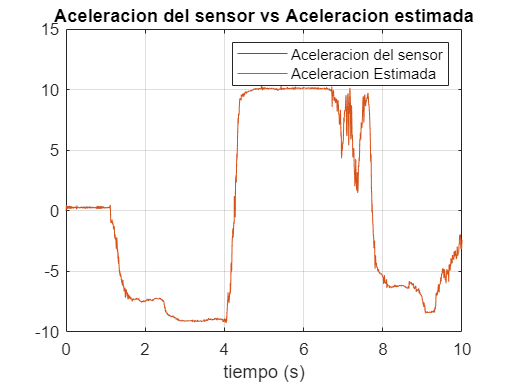

figure()
subplot(1,1,1)
plot(n,Aceleracion)
hold on
plot(n,n_sensor)
grid()
hold off
legend('Aceleracion del sensor','Aceleracion Estimada')
% hold off
xlabel('tiempo (s)')
title('Aceleracion del sensor vs Aceleracion estimada')

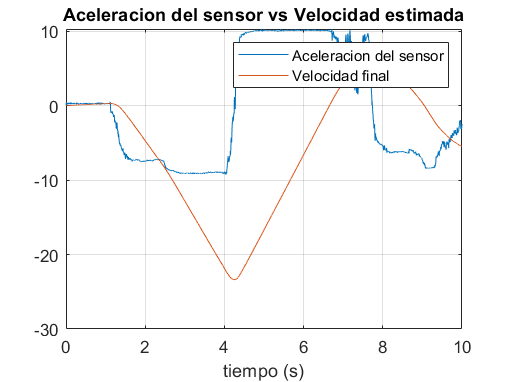


figure()
subplot(1,1,1)
plot(n,Aceleracion)
hold on
plot(n,V_final)
grid()
hold off
legend('Aceleracion del sensor','Velocidad final')
% hold off
xlabel('tiempo (s)')
title('Aceleracion del sensor vs Velocidad estimada')

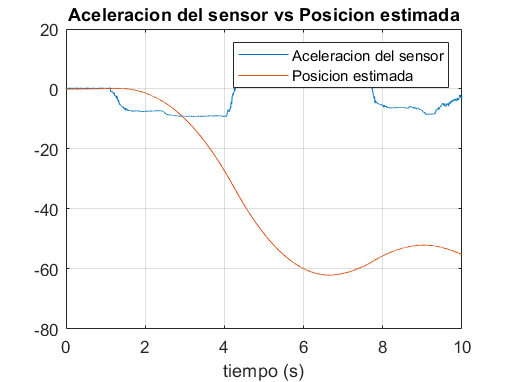


figure()
subplot(1,1,1)
plot(n,Aceleracion)
hold on
plot(n,Posicion)
grid()
hold off
legend('Aceleracion del sensor','Posicion estimada')
% hold off
xlabel('tiempo (s)')
title('Aceleracion del sensor vs Posicion estimada')

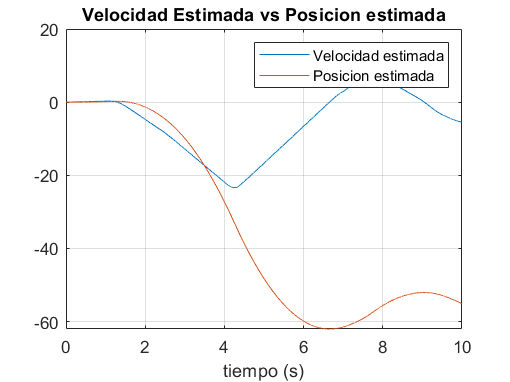


figure()
subplot(1,1,1)
plot(n,V_final)
hold on
plot(n,Posicion)
grid()
hold off
legend('Velocidad estimada','Posicion estimada')
% hold off
xlabel('tiempo (s)')
title('Velocidad Estimada vs Posicion estimada')